# Actividad 3(Evluación)

Alan Iván Flores Juárez | A01736001

%Limpieza de pantalla
clear all
clc

**Robot manipulador**

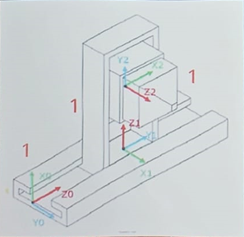

%Declaración de variables simbólicas
syms t l1(t) l2(t) l3(t)

%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[1 1 1];

%Creamos el vector de coordenadas articulares
Q= [l1, l2, l3];
disp('Coordenadas generalizadas');

Coordenadas generalizadas


pretty (Q);

(l1(t), l2(t), l3(t))




%Creamos el vector de velocidades generalizadas
Qp= diff(Q, t);
disp('Velocidades generalizadas');

Velocidades generalizadas


pretty (Qp);

/  d         d         d       \
| -- l1(t), -- l2(t), -- l3(t) |
\ dt        dt        dt       /



%Número de grado de libertad del robot
GDL= size(RP,2); %Siempre es 2, por el número de columnas
GDL_str= num2str(GDL);


%Junta 1 
%Posición de la junta 1 respecto a 0
P(:,:,1)= [0; 0; l1];

Dado que el eje Z inicia alineado con el eje de movimiento de nuestra primera junta L1, el desplazamiento de la misma se realiza sobre el eje Z.

%Matriz de rotación de la junta 1 respecto a x1 a 90
R(:,:,1)= [1 0  0;
           0 0  1;
           0 -1 0];

Para modificar la horientación del eje Z para que este coincida con nuestro seguno eje de movimiento L2, se realiza una rotación en el eje X a 90 grados.

%Junta 2
%Posición de la junta 2 respecto a 0
P(:,:,2)= [l3; 0; l2];

Dentro de nuestro nuevo marco de referencia, el movimiento de nuestro segundo eje de movimiento (L2) coincide con el eje Z, mienstras que nuestro tercer eje de movimiento (L3) coincide con nuestro eje X. Por lo que se indica en el vector de posición.

%Matriz de rotación de la junta 1 respecto a y -90
R(:,:,2)= [0 0 1;
           0 0 0;
           -1 0 0];

Por último se realiza la rotación en y a -90 grados para alinear el eje Z con nuestro último eje de movimiento L3.

%Junta 3
%Posición de la junta 3 respecto a 0
P(:,:,3)= [0; 0; 0];
%Matriz de rotación de la junta 1 respecto a 0
R(:,:,3)= [1 0 0;
           0 1 0;
           0 0 1];


Referencia Inercial     Primera Transformación   Segunda Transformación

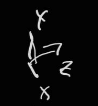          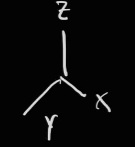          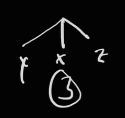

%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 
%Inicializamos las INVERSAS de las matrices de rotación vistas desde el marco de referencia inercial
RO_inv(:,:,GDL)= R(:,:,GDL); 

for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
    pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    RO_inv(:,:,i)= transpose(RO(:,:,i));
    PO(:,:,i)= T(1:3,4,i);
end

Matriz de Transformación local A1


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1,   0   |
|                 |
| 0, -1, 0, l1(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación global T1


/ 1,  0, 0,   0   \
|                 |
| 0,  0, 1,   0   |
|                 |
| 0, -1, 0, l1(t) |
|                 |
\ 0,  0, 0,   1   /



Matriz de Transformación local A2


/  0, 0, 1, l3(t) \
|                 |
|  0, 0, 0,   0   |
|                 |
| -1, 0, 0, l2(t) |
|                 |
\  0, 0, 0,   1   /



Matriz de Transformación global T2


/  0, 0, 1, l3(t) \
|                 |
| -1, 0, 0, l2(t) |
|                 |
|  0, 0, 0, l1(t) |
|                 |
\  0, 0, 0,   1   /



Matriz de Transformación local A3


/ 1, 0, 0, 0 \
|            |
| 0, 1, 0, 0 |
|            |
| 0, 0, 1, 0 |
|            |
\ 0, 0, 0, 1 /



Matriz de Transformación global T3


/  0, 0, 1, l3(t) \
|                 |
| -1, 0, 0, l2(t) |
|                 |
|  0, 0, 0, l1(t) |
|                 |
\  0, 0, 0,   1   /




%Calculamos el jacobiano lineal de forma diferencial
disp('Jacobiano lineal obtenido de forma diferencial');

Jacobiano lineal obtenido de forma diferencial


%Derivadas parciales de x respecto a l1 y l2
Jv11= functionalDerivative(PO(1,1,GDL), l1);
Jv12= functionalDerivative(PO(1,1,GDL), l2);
%Derivadas parciales de y respecto a l1 y l2
Jv21= functionalDerivative(PO(2,1,GDL), l1);
Jv22= functionalDerivative(PO(2,1,GDL), l2);
%Derivadas parciales de z respecto a l1 y l2
Jv31= functionalDerivative(PO(3,1,GDL), l1);
Jv32= functionalDerivative(PO(3,1,GDL), l2);

%Creamos la matríz del Jacobiano lineal
jv_d=simplify([Jv11 Jv12;
              Jv21 Jv22;
              Jv31 Jv32]);
pretty(jv_d);

/ 0, 0 \
|      |
| 0, 1 |
|      |
\ 1, 0 /





%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));
            Jw_a(:,k)=[0,0,1];
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    

Jv_a= simplify (Jv_a);
Jw_a= simplify (Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ 0, 0, 1 \
|         |
| 0, 1, 0 |
|         |
\ 1, 0, 0 /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0, 0 \
|         |
| 0, 0, 0 |
|         |
\ 0, 0, 0 /





disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp');
pretty(V);

/ ________ \
|  d       |
| -- l3(t) |
| dt       |
|          |
| ________ |
|  d       |
| -- l2(t) |
| dt       |
|          |
| ________ |
|  d       |
| -- l1(t) |
\ dt       /



Como podemos observar, tiene sentido el resultado obtenido para cada uno de los ejes en base a nuestro marco de referencia inercial, ya que tenemos que L1 se desplaza en Z, l2 en Y y L3 en X, tal como se observa en nuestro dibujo.

disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp');
pretty(W);

/ 0 \
|   |
| 0 |
|   |
\ 0 /



A la vez al ser un robot únicamente de juntas prismaticas, tiene sentido que no tenga velocidad angular en ninguno de los ejes.